# Project 2: Malaria Dectection on Cell Images (Transfer Learning)

**ECE 595**

**Author**: Connor Prikkel*

*: (Based on the previous work of Barath Narayanan Narayanan, Redha Alia, Russell C. Hardie)

**Date**: 11/30/23

**Note**: Any steps directly repeated from the CNN Architecture are fully explained and covered in the CNN Architecture live script.

% Images datapath – Please modify your path accordingly
datapath='D:\Connor\ECE 595\Project 2\cell_images\cell_images';

% Image datastore
img_datastore = imageDatastore(datapath, ...
'IncludeSubfolders',true, ...
'LabelSource','foldernames');

% Determine amount of each label
total_split = countEachLabel(img_datastore)

total_split = 2×2 table
       Label       Count
    ___________    _____

    Parasitized    13779
    Uninfected     13779



% Store labels in a variable
labels = img_datastore.Labels;

% Can use built in methods that are part of Deep Learning toolbox and discussed in paper

% Split the data into training and testing datasets
train_percent = 0.8;
[img_train,img_test] = splitEachLabel(img_datastore, train_percent, 'randomize');

% Further split the training dataset in half to form the validation dataset
valid_percent = 0.1;
[img_valid, img_train] = splitEachLabel(img_train, valid_percent, 'randomize');

train_split=countEachLabel(img_train);

% Visualize part of the dataset to ensure correctly loaded

num_images = length(img_datastore.Labels);


**Note**: As the same dataset is loaded and the same preprocessing function and data augmentation are applied to this data, there is no need to visualize the images again. For data visulization, please see the CNN Architecture live script.

## Transfer Learning Approach without Preprocessing

In place of constructing a CNN fully from scratch, an existing and well-tested architecture is loaded and its layers are modified to better fit this classification problem. 'ResNet50' is chosen for this classification task over VGG16 and Inceptionv3 for two major reasons. First of all, it has a far fewer number of parameters than VGG16 at around 25 million compared to VGG16's ~138 million. Secondly, although Inceptionv3 has a similar amount of parameters to ResNet50 and can run multiple operations in parallel, it is better suited for recognizing many features from multiple perspectives and is much more complex to modify.

For these reasons, ResNet50 is chosen for this classification task.

% Load ResNet50
net = resnet50;

% Parameter to define the number of units in the new fc layer -
% 'numClasses' is equal to 2 in this case as there are two types of labels
numClasses = numel(categories(img_train.Labels));

% Define layer graph
lgraph = layerGraph(net);

% Clear the existing resnet architecture
clear net;


% Define new layers

% Ref: (https://www.mathworks.com/matlabcentral/answers/398045-can-someone-explain-to-me-the-meaning-of-these-numbers-is-this-line-of-code)
% 'WeightLearnRateFactor' is the factor by which the learning rate is
% scaled for the weights in this layer compared to the global learning rate
% 'BiasLearnRateFactor' is a similar factor that scales the learning
% rate, except for the biases in this layer.

new_fc = fullyConnectedLayer(numClasses, ...
    'Name', 'custom_fc', ...
    'WeightLearnRateFactor', 8, ...
    'BiasLearnRateFactor', 8);

new_softmax = softmaxLayer('Name', 'custom_softmax');
new_classification = classificationLayer('Name', 'custom_classification');


% Replace the last three layers with new layers using replaceLayer()
% function
lgraph = replaceLayer(lgraph, 'fc1000', new_fc);
lgraph = replaceLayer(lgraph, 'fc1000_softmax', new_softmax);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', new_classification);

% Resize all training/validation/test images to [224 224] for ResNet
% architecture
img_train.ReadFcn=@(filename)reshape_image(filename, [224 224]);
img_valid.ReadFcn=@(filename)reshape_image(filename, [224 224]);
img_test.ReadFcn=@(filename)reshape_image(filename, [224 224]);  

In the above code, the last three layers of ResNet50: a fullyConnectedLayer with 1000 units, softmaxLayer, and classificationLayer, are removed and replaced by new different fullyConnectedLayer and the same softmaxLayer and classificationLayer. The number of hidden units is dropped from 1000 to 2 as the output of the last fullyConnectedLayer must match the number of classes. The learning rate factors for the weights and biases are increased twentyfold in this layer to compensate for removing 99.8% of the weights in the layer.

### Training

To keep a level of consistency, the training hyperparameters are kept the same between training on the different networks, except the number of epochs is reduced to 2 to save on training time.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:03:24 |       57.81% |       52.36% |       0.7093 |       1.1207 |          0.0100 |
|       1 |          50 |       00:29:05 |       61.72% |       56.99% |       1.1351 |       1.3843 |          0.0100 |
|       1 |         100 |       00:54:15 |       61.72% |       56.67% |       1.2119 |       1.2185 |          0.0100 |
|       1 |         150 |       01:36:36 |       64.84% |       60.98% |       0.7260 |   

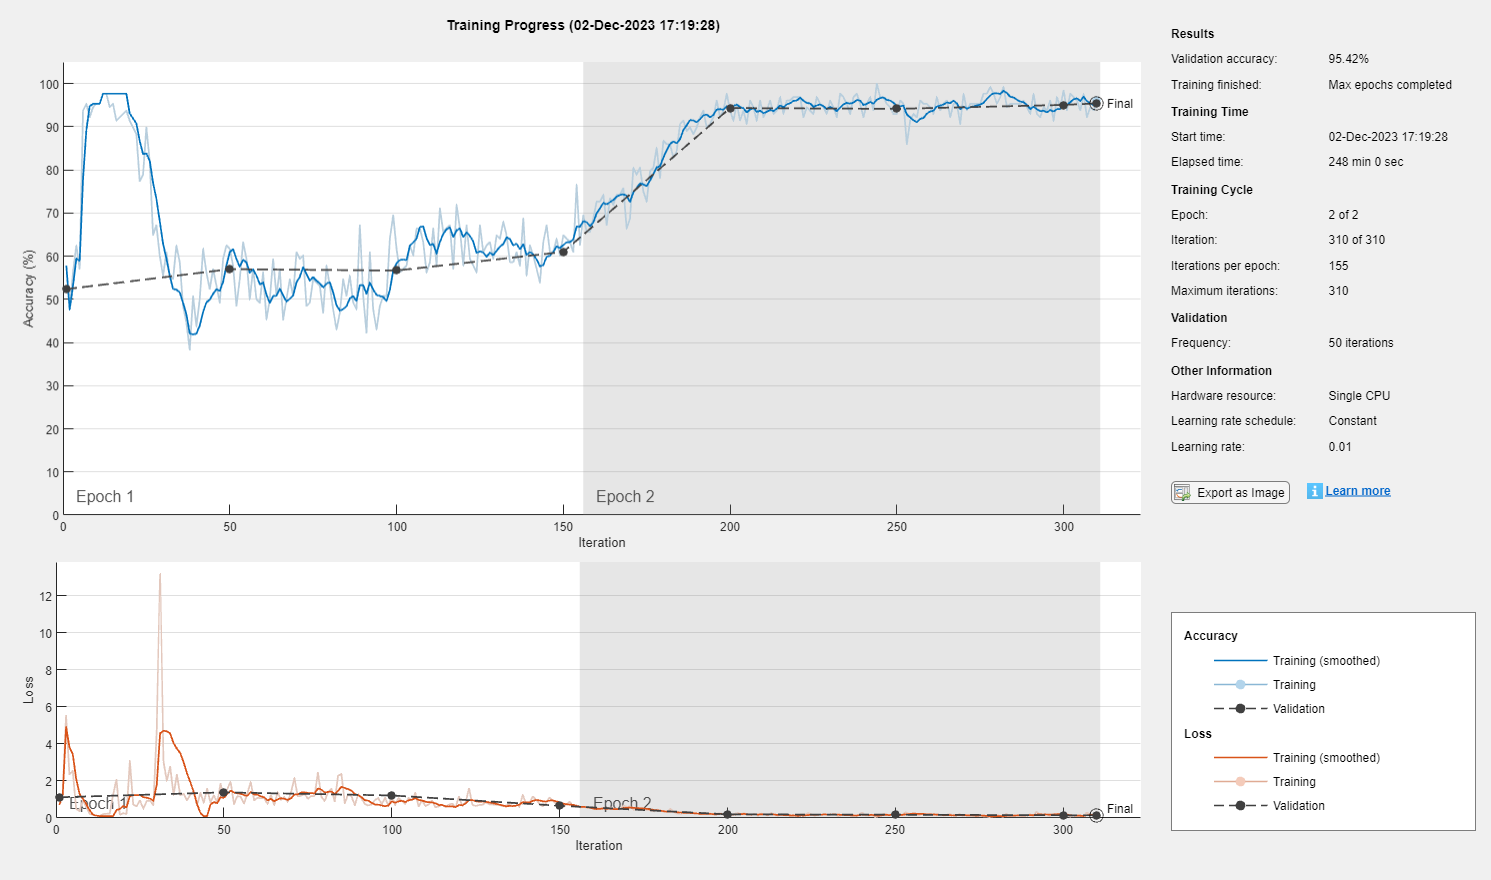

options = trainingOptions('sgdm','MaxEpochs', 2, 'MiniBatchSize', 128, ...
    'ValidationData', img_valid, ...
    'Shuffle', 'every-epoch', ...
    'ValidationFrequency', 50, ...
    'Plots', 'training-progress', ...
    'ValidationPatience', 4);

% Train the Network
netTransfer = trainNetwork(img_train, lgraph, options);

### Testing

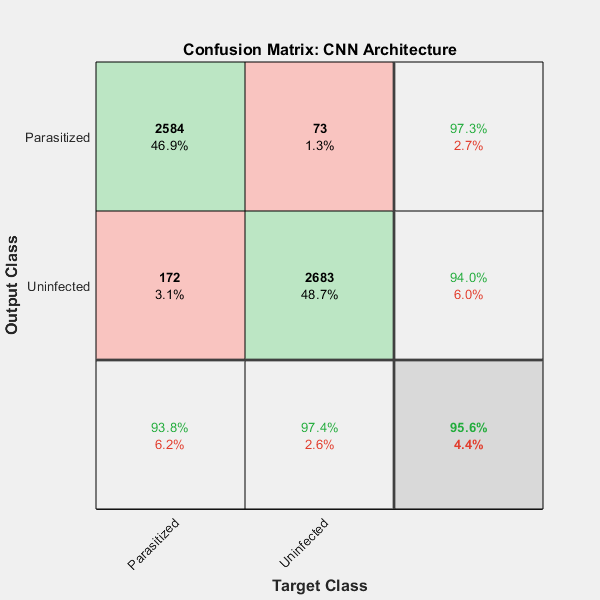

% Predict Test Labels using classify command
[predicted_labels, posterior] = classify(netTransfer, img_test);

% Actual Labels
actual_labels = img_test.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels, predicted_labels)
title('Confusion Matrix: CNN Architecture');

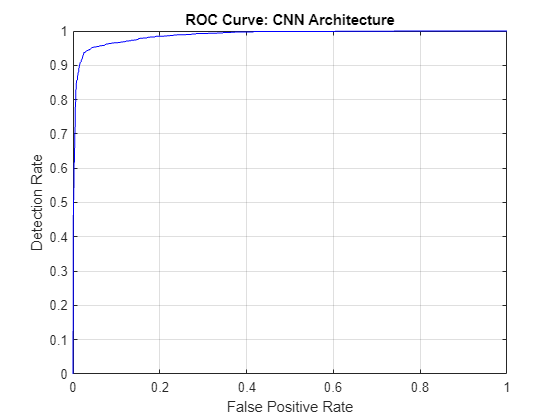


test_labels = double(nominal(img_test.Labels));

% ROC Curve - Our target class is the first class in this scenario.
[fp_rate, tp_rate, T, AUC] = perfcurve(test_labels, posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
title('ROC Curve: CNN Architecture')
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC value
AUC

AUC = single
0.9876

## Transfer Learning Approach with Preprocessing

% Utilize recommended augmentedImageDatastore for faster
% resizing/transforming whilst preprocessing
img_train.ReadFcn=@(filename)preprocess_malaria_images(filename, [224, 224]);
img_valid.ReadFcn=@(filename)preprocess_malaria_images(filename, [224, 224]);

### Training

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:03:40 |       56.25% |       56.03% |       0.7554 |       0.8494 |          0.0100 |
|       1 |          50 |       00:36:39 |       93.75% |       95.51% |       0.1762 |       0.1555 |          0.0100 |
|       1 |         100 |       01:07:03 |       92.19% |       90.88% |       0.1720 |       0.7683 |          0.0100 |
|       1 |         150 |       01:40:53 |       94.53% |       93.69% |       0.3607 |   

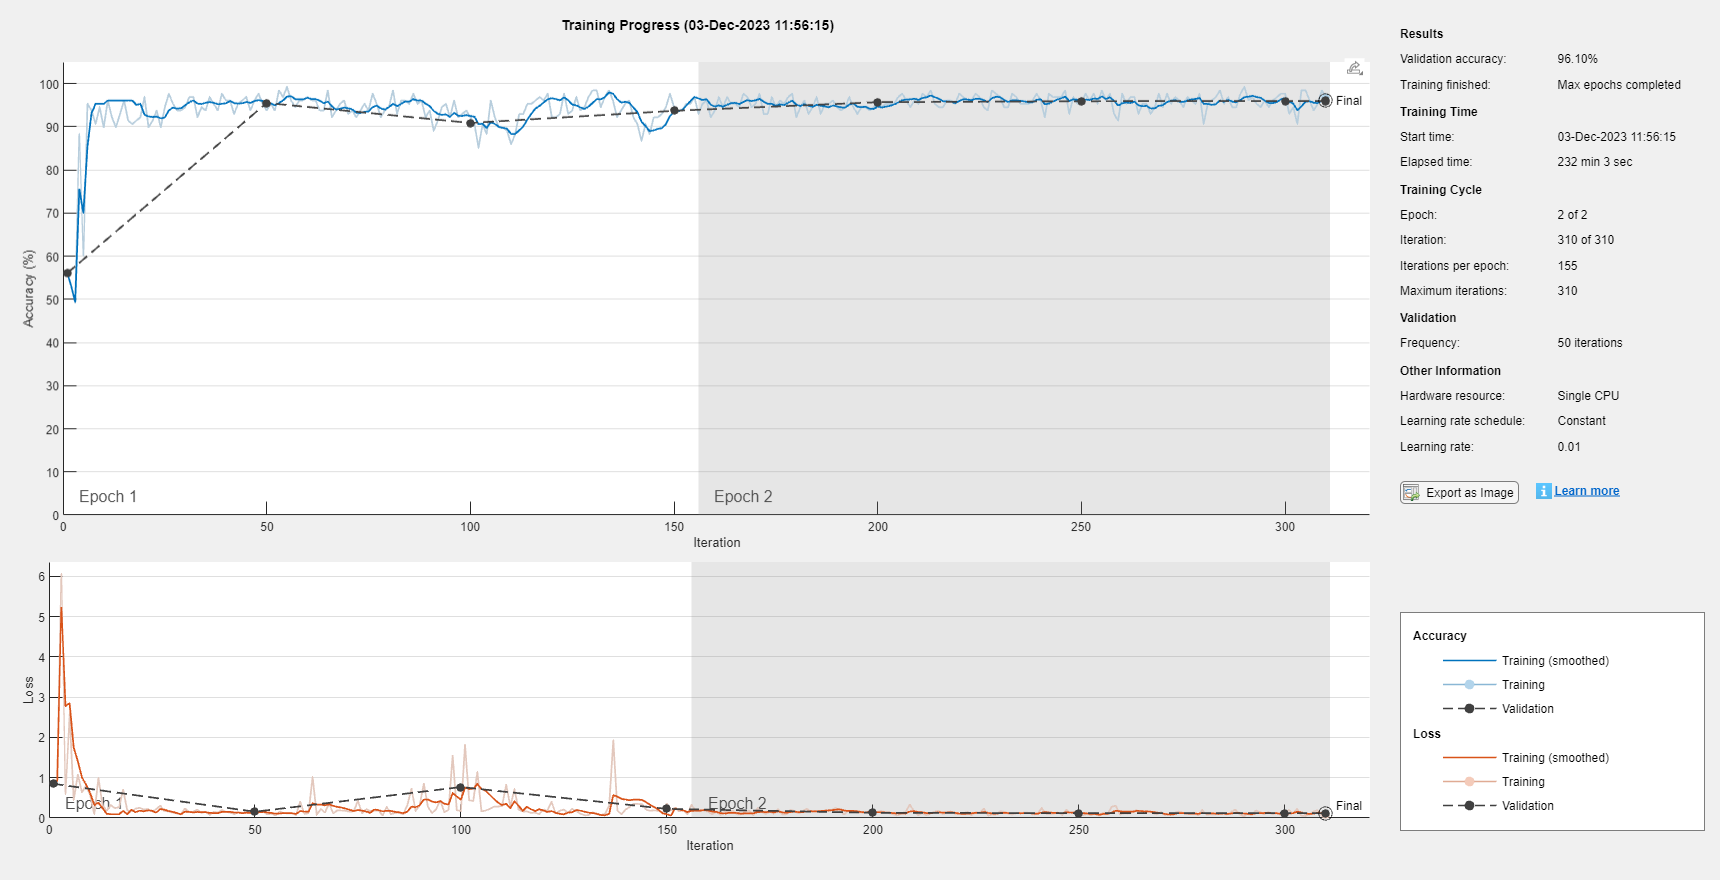

% Train the Preprocessed Network
netTransfer_preprocessed = trainNetwork(img_train, lgraph, options);

### Testing

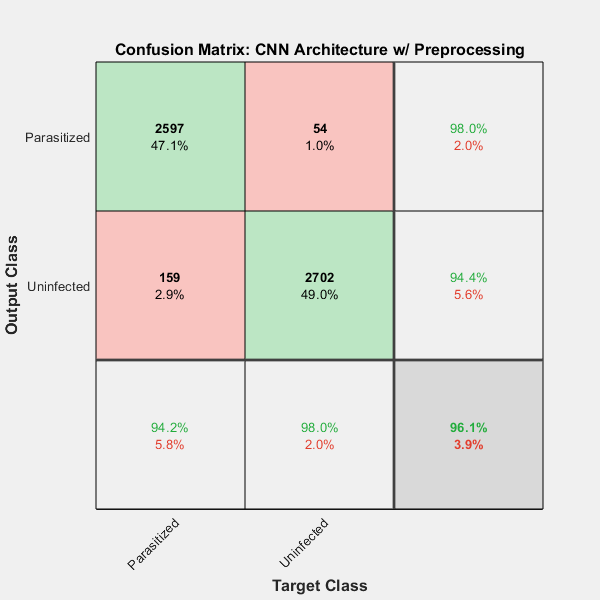

% Preprocess the test cases similar to the training
img_test.ReadFcn=@(filename)preprocess_malaria_images(filename, [224, 224]);

% Predict Test Labels using classify command
[predicted_labels, posterior] = classify(netTransfer_preprocessed, img_test);

% Confusion Matrix
figure;
plotconfusion(actual_labels, predicted_labels)
title('Confusion Matrix: CNN Architecture w/ Preprocessing');

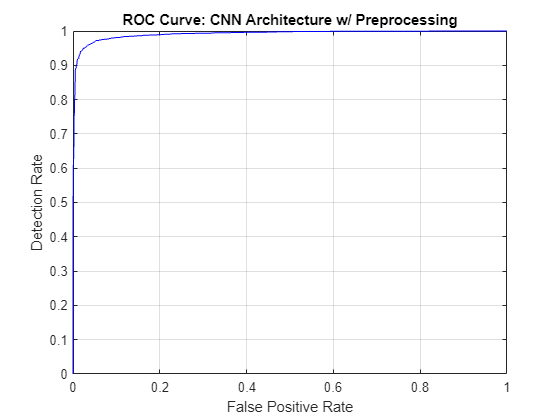


% ROC Curve - Our target class is the first class in this scenario.
[fp_rate, tp_rate, T, AUC] = perfcurve(test_labels, posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
title('ROC Curve: CNN Architecture w/ Preprocessing')
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC value
AUC

AUC = single
0.9915

## Transfer Learning Approach with Preprocessing and Data Augmentation

% Data Augmentation (Ref: https://www.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html)

% Configure a set of preprocessing options for image augmentation
% 'RandRotation': Rotates the image anywhere between -90 and 90 degrees
% 'RandXReflection': 50 % chance of flipping the image about the x-axis
% 'RandYReflection': 50 % chance of flipping the image about the y-axis
image_augumenter=imageDataAugmenter('RandRotation', [-90 90], 'RandXReflection', true,'RandYReflection', true);

aug_img_train_datastore = augmentedImageDatastore([224 224], img_train,'DataAugmentation', image_augumenter);
aug_img_valid_datastore = augmentedImageDatastore([224 224], img_valid,'DataAugmentation', image_augumenter);

### Training

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:03:53 |       49.22% |       55.08% |       0.8101 |       1.0703 |          0.0100 |
|       1 |          50 |       00:36:21 |       95.31% |       93.74% |       0.2327 |       0.3966 |          0.0100 |
|       1 |         100 |       01:08:19 |       92.19% |       93.01% |       0.2664 |       0.2246 |          0.0100 |
|       1 |         150 |       01:37:15 |       93.75% |       95.10% |       0.2592 |   

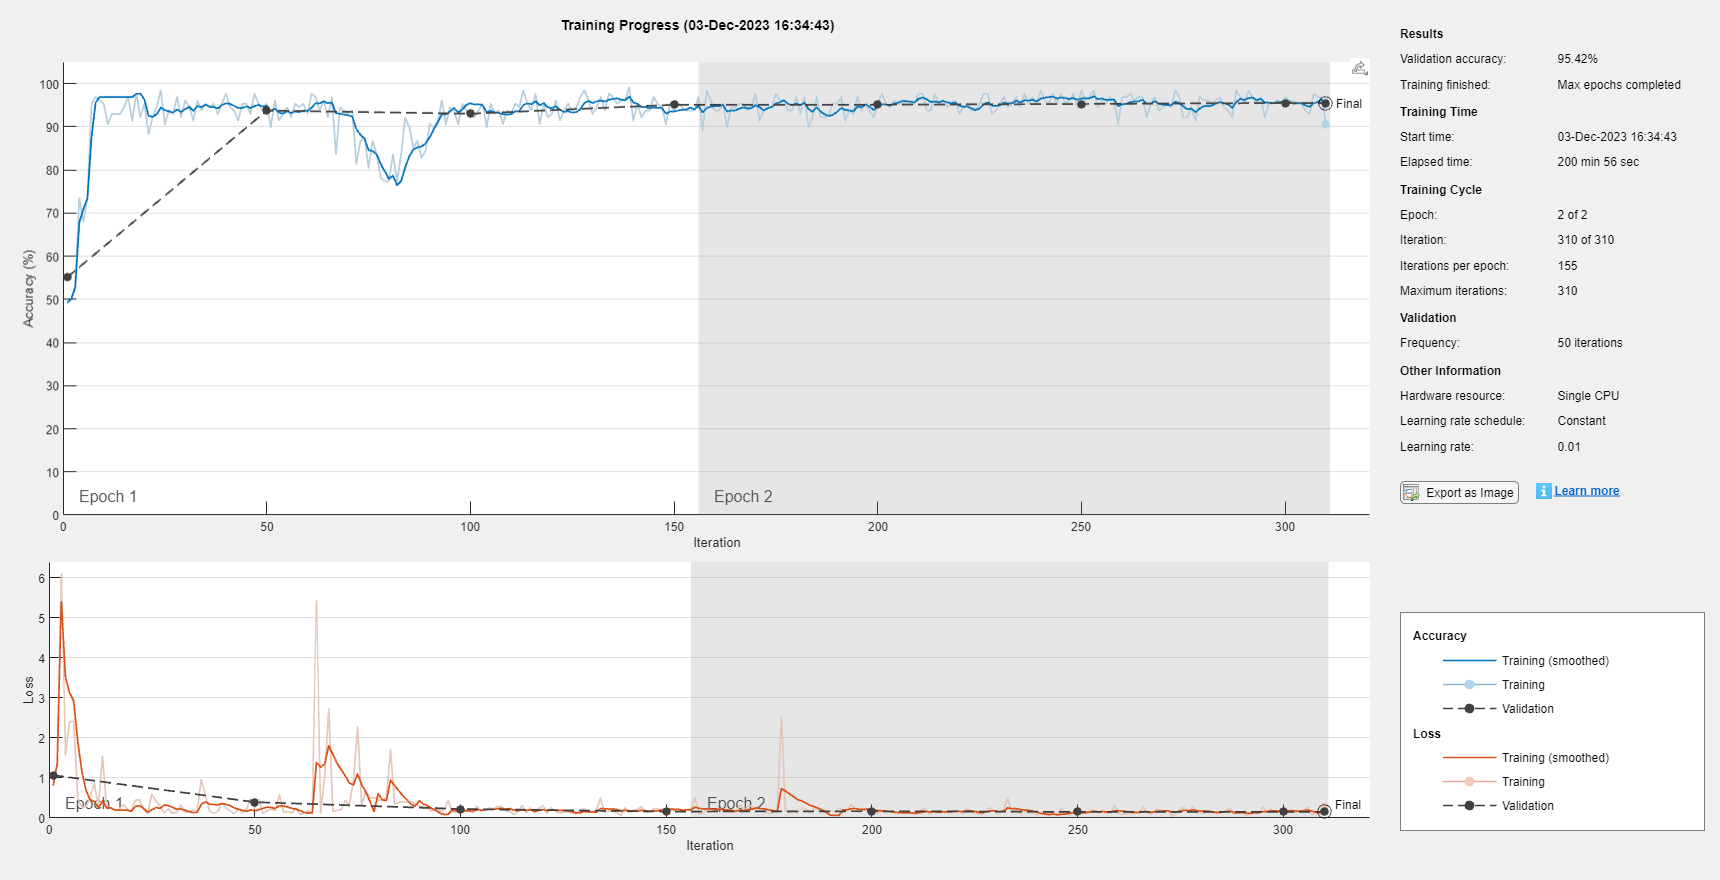

% Train the Preprocessed and Augmented Network
netTransfer_preprocessed_augmented = trainNetwork(aug_img_train_datastore, lgraph, options);

### Testing

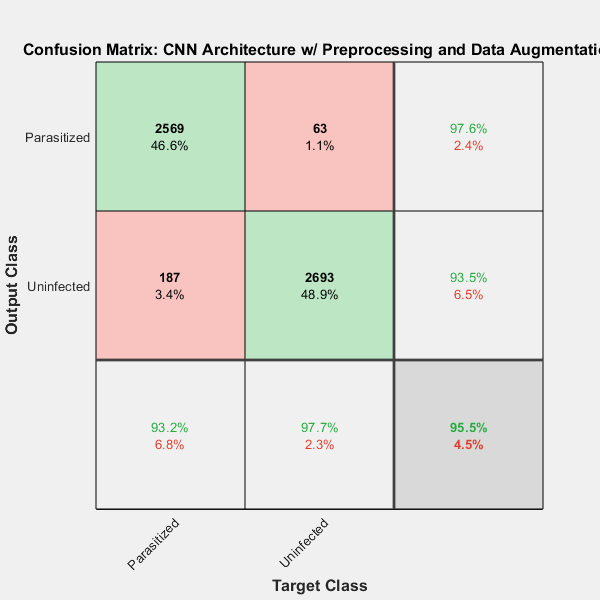

% Augment the test cases similar to the training
aug_img_test_datastore = augmentedImageDatastore([224 224], img_test,'DataAugmentation', image_augumenter);

% Predict Test Labels using classify command
[predicted_labels, posterior] = classify(netTransfer_preprocessed_augmented, img_test);

% Confusion Matrix
figure;
plotconfusion(actual_labels, predicted_labels)
title('Confusion Matrix: CNN Architecture w/ Preprocessing and Data Augmentation');

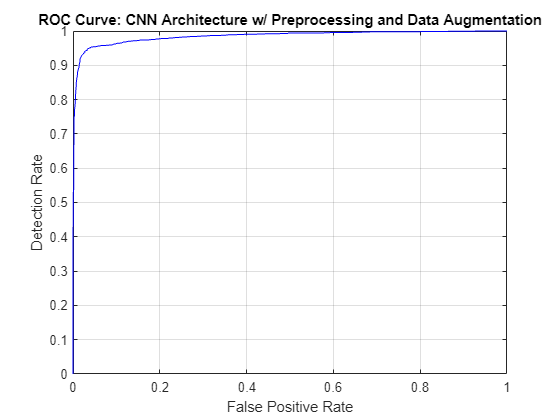


% ROC Curve - Our target class is the first class in this scenario.
[fp_rate, tp_rate, T, AUC] = perfcurve(test_labels, posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
title('ROC Curve: CNN Architecture w/ Preprocessing and Data Augmentation')
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC value
AUC

AUC = single
0.9848

## Results & Suggestions for Improvement

All three types of input data achieved a respectable 95 - 97% accuracy on each indivial subset, except for the training accuracy with regards to the preprocessed and augmented data. The gap between the preprocessed and augmented data's training accuracy and the training accuracy for the other types of data is alarmingly large; it is much smaller. As the preprocessed and augmented's validation and test accuracy are closer to the results generated for the other input data, the model is likely underfitting. This could be most easily remedied by training for more epochs, seeing as the the model trained over thirty minutes faster on this input data when compared to the others.

Using contrast enhancement on the input data actually improved ResNet50's accuracy on each individual dataset when compared to the data with no preprocessing, highlighting that it may be a good preprocessing technique when considering this model and classification task. 

Although ResNet50 achieved comparably good results to the custom CNN architecture in terms of classifying of the malaria dataset, I believe the custom CNN architecture is a much better choice for this classification problem. This is largely due to the signficant increase in learnable parameters and training time required for ResNet50. On top of this, the custom CNN architecture was able to achieve a higher test accuracy for all three categories of input data. ResNet50 and transfer learning with larger, modern models are more suitable for more complex tasks with a variety of target classes.

## Reshape Function

function [Iout] = reshape_image(filename,image_size)
% This function resizes all images to a fixed size
%
% Author: Barath Narayanan
% Date: 11/16/2021
%

% Read the images
I=imread(filename);

% Output Image
Iout=imresize(I,image_size);

end

## Preprocessing Function

function I_adapthisteq = preprocess_malaria_images(filename, desired_size)

% This function preprocesses malaria images using contrast enhancement and
% resizes the image
% Author: Connor Prikkel
% Ref: https://www.mathworks.com/help/images/contrast-enhancement-techniques.html

% Read the Image
I = imread(filename);

% Some images might be grayscale, replicate the image 3 times to
% create an RGB image.

if ismatrix(I)
  I = cat(3,I,I,I);
end

% Convert the image from RGB color space to L*a*b* color space
I_lab = rgb2lab(I);

% Values of luminosity span a range from 0 to 100 
% Scale values to range [0 1]
max_luminosity = 100;
L = I_lab(:,:,1)/max_luminosity;


% Contrast-Limited Adaptive Histogram Equalization - operates on small
% sections of the intensity image at a time
I_adapthisteq = I_lab;
I_adapthisteq(:,:,1) = adapthisteq(L)*max_luminosity;
I_adapthisteq = lab2rgb(I_adapthisteq);

% Resize the image
I_adapthisteq = imresize(I_adapthisteq, [desired_size(1) desired_size(2)]);

end